# Fourier Transform

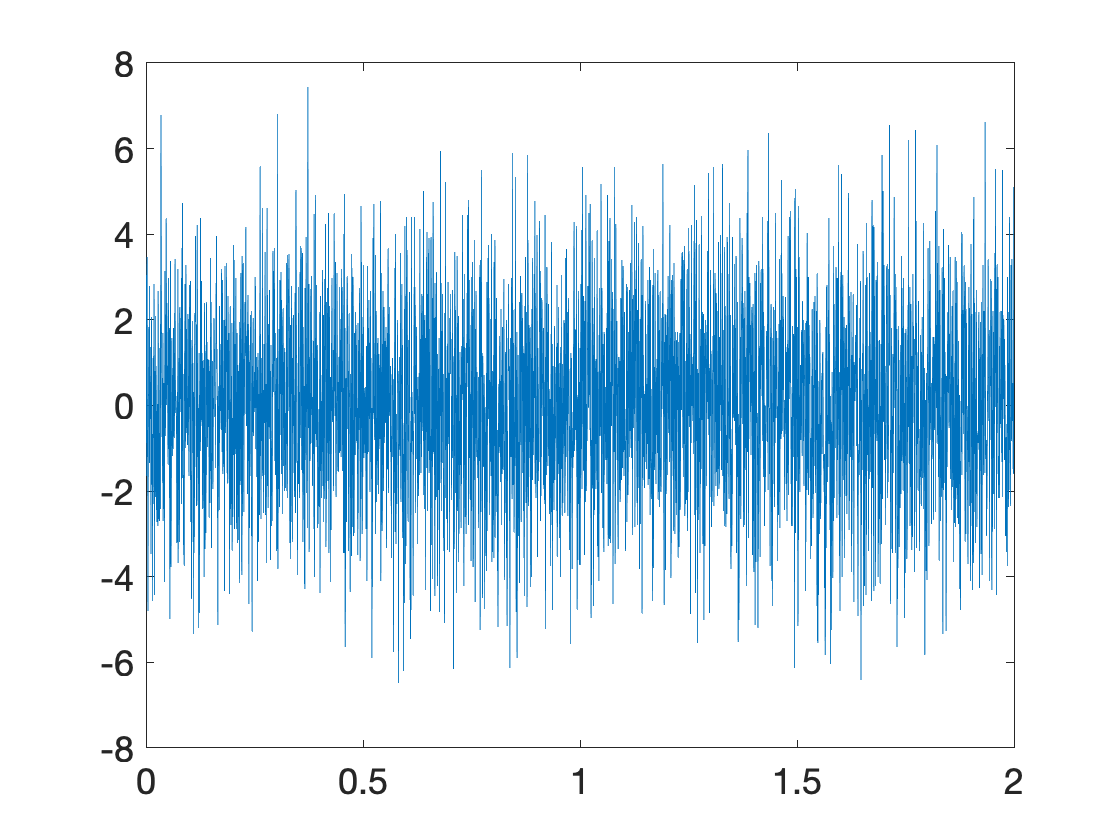

file = readtable('data.csv');
t = file{:,1};
X = file{:,2};
plot(t, X)

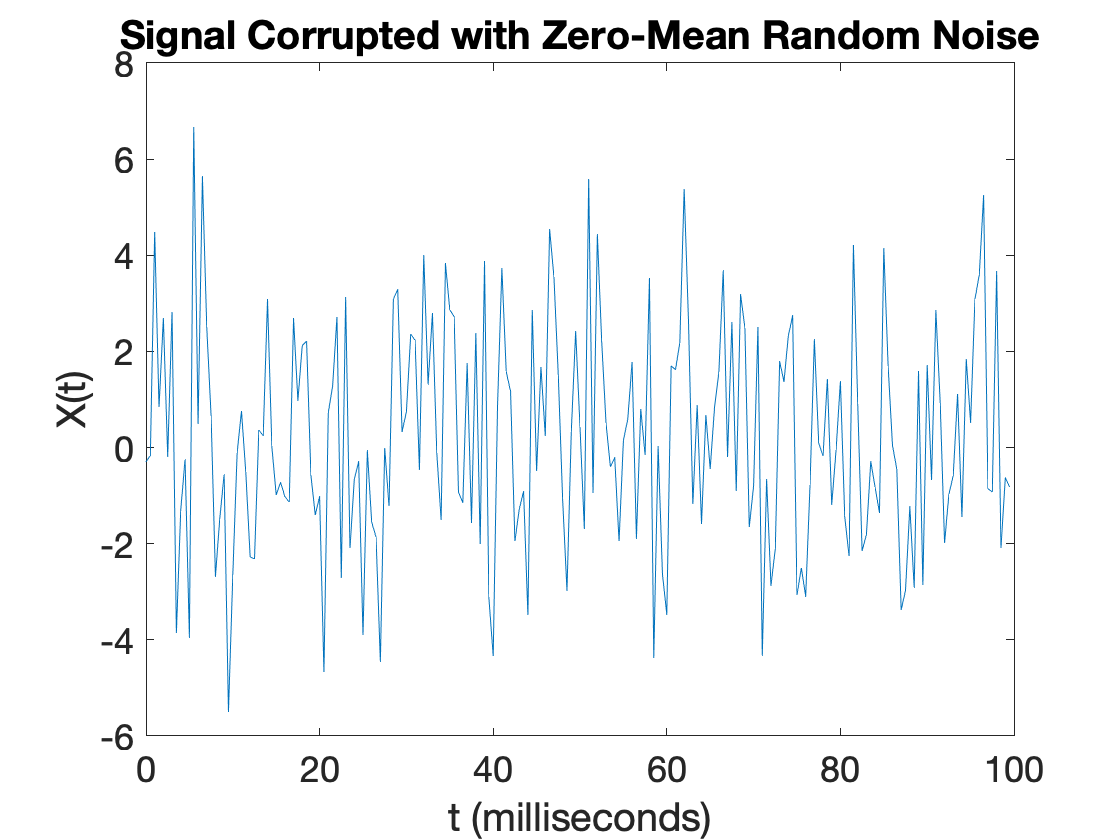


Fs = 2000; % Sampling frequency 
T = 1/Fs; % Sampling period
L = 4000; % Length of signal
t = (0:L-1)*T; % Time vector
S = 0.7 * sin(2*pi*65*t) + sin(2*pi*180*t); % Signal Values 
X = S + 2*randn(size(t)); % Adding in noise

set(groot,'DefaultAxesFontSize',18)
figure(1)
plot(1000*t(1:200),X(1:200)) 
%Changed time to milliseconds and zoomed in to first 200 points
title('Signal Corrupted with Zero-Mean Random Noise')
xlabel('t (milliseconds)')
ylabel('X(t)')

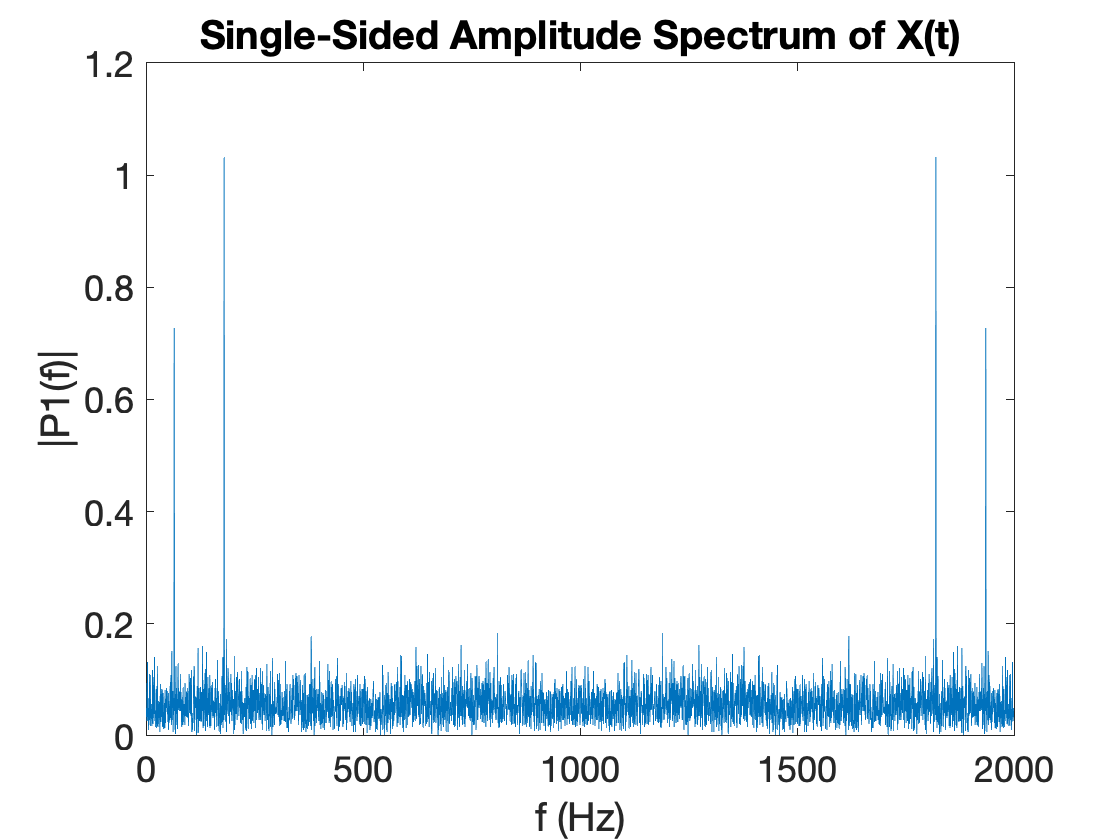


Y = fft(X);% Fast Fourier Transform
P = abs(Y*2/L); % abs value and Normalize
% abs() removes the negative and imaginary
% 2/L normalizes the amplitudes

f= Fs*(0:L-1)/L; % Frequency list in Hz

figure(2)
plot(f,P)
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')

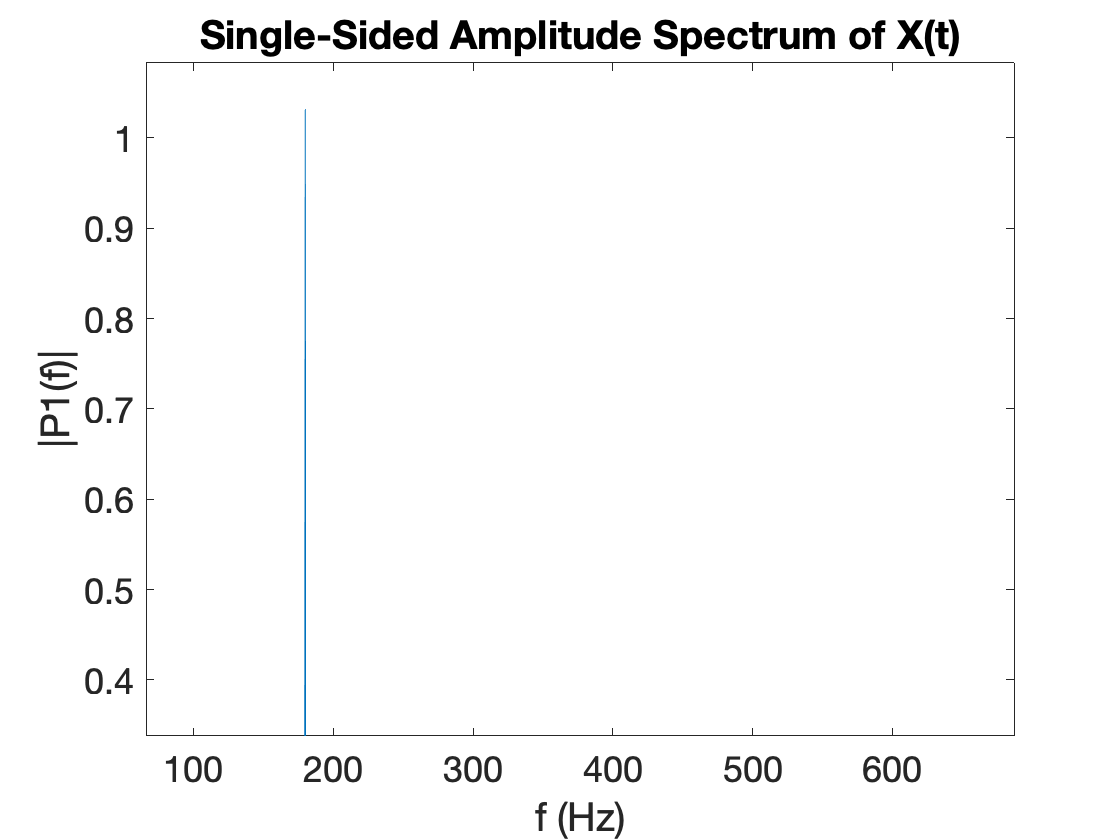


% We see two signals we expected and 2 we didn't expect
% Everything after 1/2 Fs is a reflection about 1/2 Fs 
% To correct only plot the first half

plot(f(1:L/2),P(1:L/2))
%Looking at first 2000 points (0-1000 Hz) 
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)') 
ylabel('|P1(f)|')

### Example: Guitar string

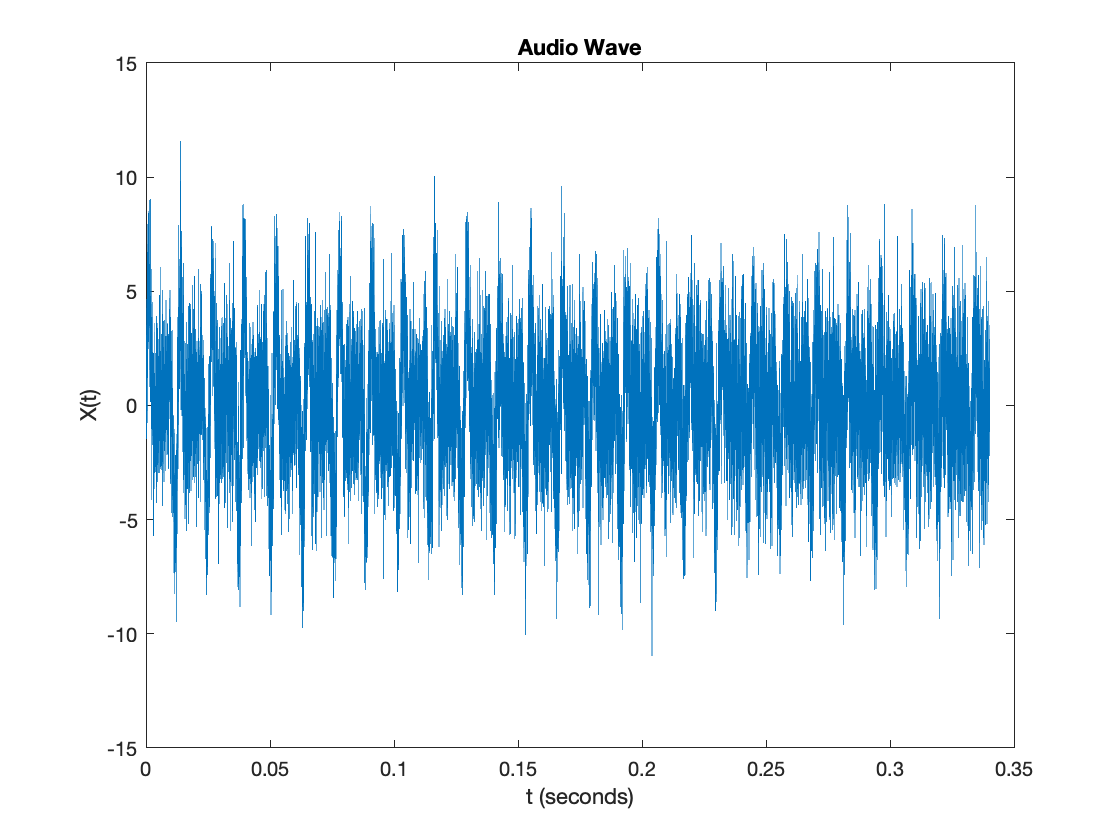

file = readtable('guitar_low_E.csv');
t = file{:,1};
X = file{:,2};
plot(t,X)
title('Audio Wave')
xlabel('t (seconds)')
ylabel('X(t)')


Fs = 44100; % Sampling frequency 
L = size(X,1); % Data length (Length of signal)

Y = fft(X) % Fourier Transform

Y = 	1.0e+04 *

   0.0473 + 0.0000i
   0.0631 - 0.0026i
   0.0186 + 0.0240i
   0.0691 - 0.0257i
   0.0273 - 0.0014i
   0.0045 - 0.0177i
   0.0508 + 0.0236i
   0.0082 - 0.0004i
   0.0457 - 0.0060i
   0.0396 - 0.0305i


P = abs(Y*2/L) % Realize and Normalize

P =     0.0630
    0.0842
    0.0405
    0.0984
    0.0365
    0.0243
    0.0747
    0.0109
    0.0614
    0.0667


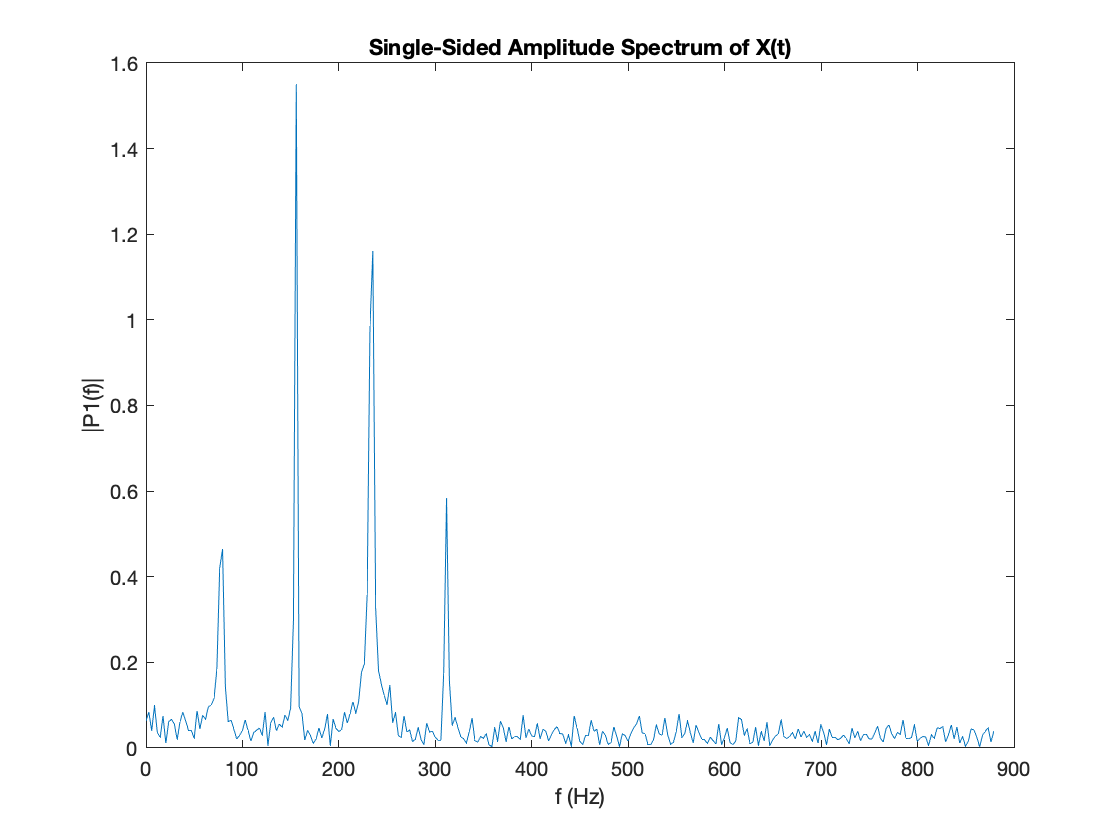

f = Fs*(0:L-1)/L; % Make bin widths

plot(f(1:300), P(1:300)) 
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)') 
ylabel('|P1(f)|')

$f\lambda =\sqrt{\frac{T}{\rho }}$         $T=f^2 \lambda^2 \rho$        Can calculate $T_0$ as we know f's needed, use $\lambda =2L$ can get $\rho$


$$C=\frac{\Delta T}{\left(\Delta \frac{L}{L}\right)}$$
           
$$\Delta L=\frac{\left(T_1 -T_0 \right)L}{C}$$
             
$$\mathrm{peg}\;\mathrm{turns}=\frac{\Delta L}{0\ldotp 005\;\left(\frac{m}{\mathrm{turn}}\right)}=\;$$

$$\frac{1}{0\ldotp 005\;\left(\frac{m}{\textrm{turn}}\right)}\;\frac{\left(T_1 -T_0 \right)L}{C}\;$$



$$\mathrm{peg}\;\mathrm{turns}\;=\frac{1}{0\ldotp 005\;\left(\frac{m}{\textrm{turn}}\right)}\frac{\left.{\left(f\right.}_1^2 \lambda^2 \rho -f_0^2 \lambda^2 \rho \right)}{C}=\frac{4L^3 \rho }{0\ldotp 005\;\left(\frac{m}{\textrm{turn}}\right)}\frac{\left(f_1^2 -f_0^2 \right)}{C}\;$$


### Practice Test

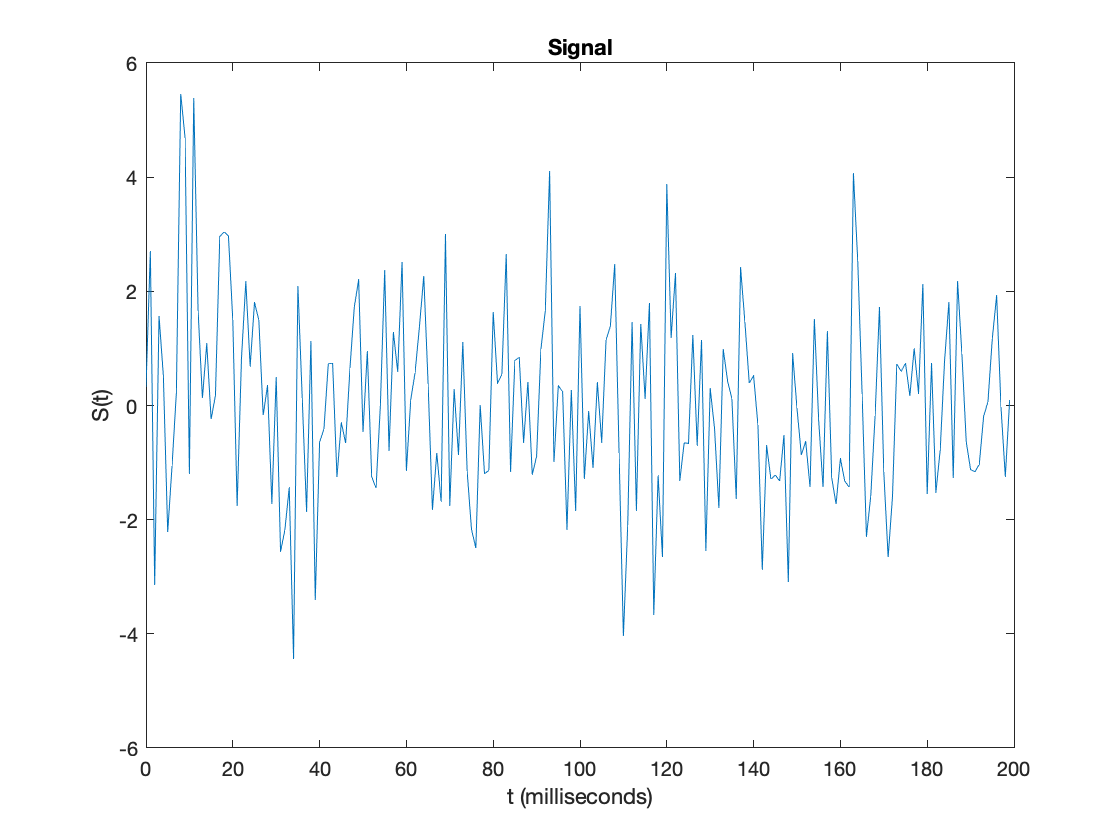

Fs = 1000; % Sampling frequency 
T = 1/Fs; % Sampling period
L = 5000; % Length of signal
t = (0:L-1)*T; % Time vector
A=1;
S = A*cos(100*pi*t-50).*sin(150*pi*t+100)+1.5*A*randn(size(t));
% plot the signal
figure
plot(Fs*t(1:200),S(1:200)) 
title('Signal')
xlabel('t (milliseconds)') 
ylabel('S(t)')

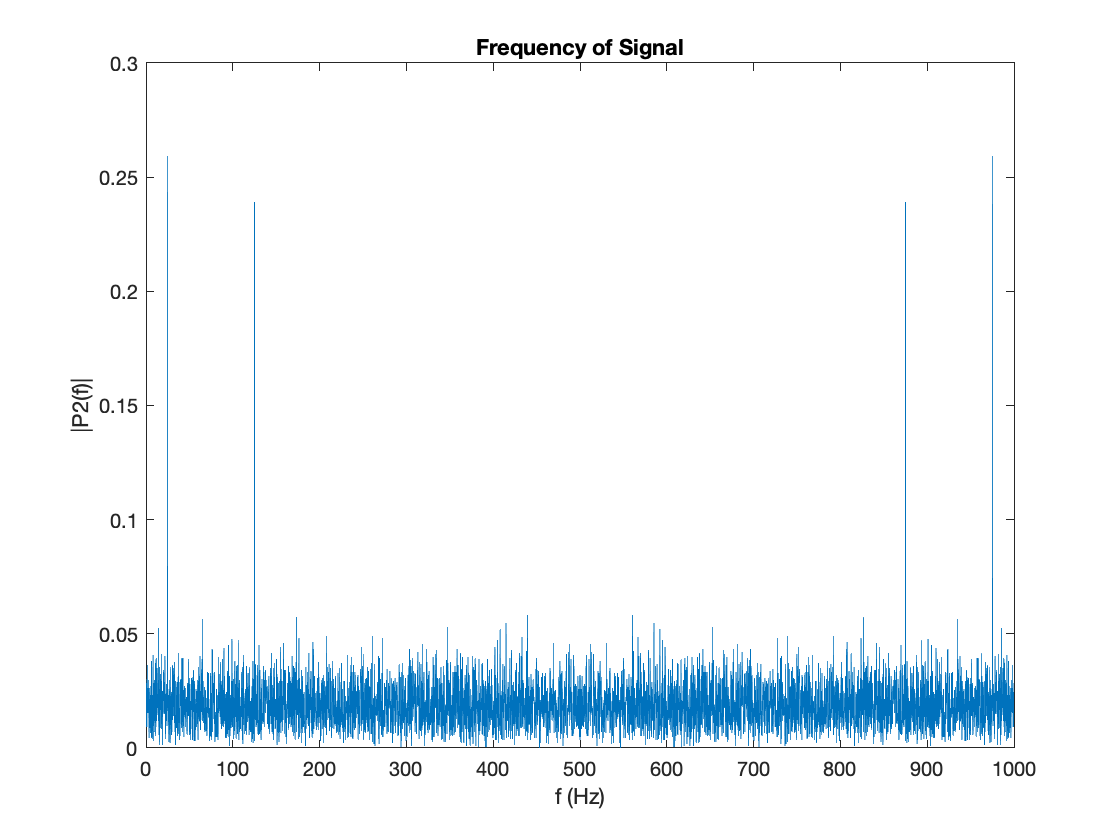

%FFT
Y = fft(S);
P2=abs(Y/L); %strength of the FFT signal 
f = Fs*(0:L-1)/L; %frequency bins figure
plot(f,P2)
title('Frequency of Signal')
xlabel('f (Hz)')
ylabel('|P2(f)|')

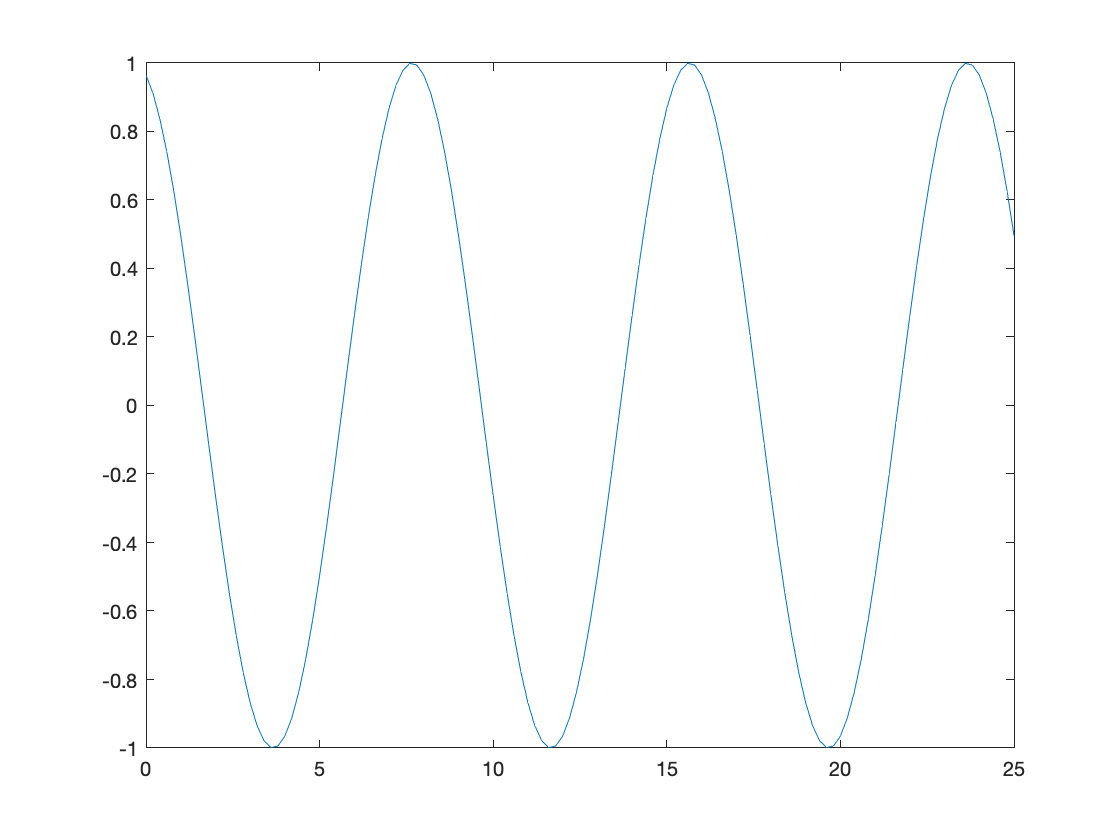


S = A*cos(2*pi*25*t-50); %frequency of 25 Hz
plot(f,S)
xlim([0,25])

# Moment of Inertia Tensor

### Practice test


$$\overset{\leftrightarrow }{I} =\;\left\lbrack \begin{array}{ccc}
I_{\textrm{xx}}  & I_{\textrm{xy}}  & I_{\textrm{xz}} \\
I_{\textrm{yx}}  & I_{\textrm{yy}}  & I_{\textrm{yz}} \\
I_{\textrm{zx}}  & I_{\textrm{zy}}  & I_{\textrm{zz}} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
\sum_i m_i {\left(y^2 +z^2 \right)}_i  & -\sum_i m_i {\left(\mathrm{xy}\right)}_i  & -\sum_i m_i {\left(\mathrm{xz}\right)}_i \\
-\sum_i m_i {\left(\mathrm{xy}\right)}_i  & \sum_i m_i {\left(x^2 +z^2 \right)}_i  & -\sum_i m_i {\left(\mathrm{yz}\right)}_i \\
-\sum_i m_i {\left(\mathrm{xz}\right)}_i  & -\sum_i m_i {\left(\mathrm{yz}\right)}_i  & \sum_i m_i {\left(x^2 +y^2 \right)}_i 
\end{array}\right\rbrack$$


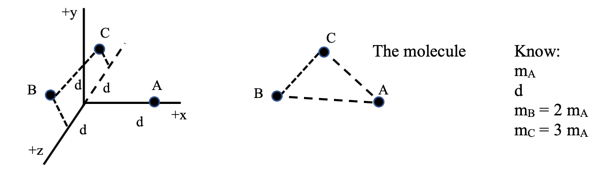


$$\overleftrightarrow{I} =\left\lbrack \begin{array}{ccc}
m_B \left(d^2 +d^2 \right)+m_C \left(d^2 +d^2 \right) & 0 & 0\\
0 & m_A d^2 +m_B d^2 +m_C d^2 \; & {-\;m}_B d^{2\;} +m_C d^2 \\
0 & {-\;m}_B d^{2\;} +m_C d^2  & m_A d^2 +m_B d^2 +m_C d^2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
10m_A d^2  & 0 & 0\\
0 & 6m_A d^2  & m_A d^2 \\
0 & m_A d^2  & 6m_A d^2 
\end{array}\right\rbrack$$
 


$$\overleftrightarrow{I} =m_A d^2 \left\lbrack \begin{array}{ccc}
10 & 0 & 0\\
0 & 6 & 1\\
0 & 1 & 6
\end{array}\right\rbrack$$


syms m_a d w_x w_y w_z L
I = [10 0 0; 0 6 1; 0 1 6];
l = [1 0 0; 0 1 0; 0 0 1];

equ = det(I - L.*l) == 0

$$equ = -L^{3}+22\,L^{2}-155\,L+350=0$$

eigenvalues = solve(equ, L)

$$eigenvalues = \left(\begin{array}{c} 5\\ 7\\ 10 \end{array}\right)$$


e_1 = (I - eigenvalues(1,:).*l)*w == [0; 0; 0]

$$e\_1 = \left(\begin{array}{c} 5\,w_{x}=0\\ w_{y}+w_{z}=0\\ w_{y}+w_{z}=0 \end{array}\right)$$

e_2 = (I - eigenvalues(2,:).*l)*w == [0; 0; 0]

$$e\_2 = \left(\begin{array}{c} 3\,w_{x}=0\\ w_{z}-w_{y}=0\\ w_{y}-w_{z}=0 \end{array}\right)$$

e_3 = (I - eigenvalues(3,:).*l)*w == [0; 0; 0]

$$e\_3 = \left(\begin{array}{c} 0=0\\ w_{z}-4\,w_{y}=0\\ w_{y}-4\,w_{z}=0 \end{array}\right)$$


$$I=\;\left\lbrack \begin{array}{ccc}
I_{\mathrm{xx}}  & I_{\mathrm{xy}}  & I_{\mathrm{xz}} \\
I_{\mathrm{yx}}  & I_{\mathrm{yy}}  & I_{\mathrm{yz}} \\
I_{\mathrm{zx}}  & I_{\mathrm{zy}}  & I_{\mathrm{zz}} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
2 & -1 & 0\\
-1 & 2 & 0\\
0 & 0 & 4
\end{array}\right\rbrack$$


syms L w_x w_y w_z
I = [2 -1 0; -1 2 0; 0 0 4];
l = [1 0 0; 0 1 0; 0 0 1];

### Principal Moments

        To find the principal moments we use the equation $\mathrm{det}\left(I-\lambda 1\right)=0$

equ = det(I - L.*l) == 0

$$equ = -L^{3}+8\,L^{2}-19\,L+12=0$$

eigenvalues = solve(equ, L)

$$eigenvalues = \left(\begin{array}{c} 1\\ 3\\ 4 \end{array}\right)$$

        Therefore, the principal moments are $\lambda_1 =1$ , $\lambda_2 =3$ , $\lambda_3 =4$

### Principal Axes

        With $\lambda_1 =1$ and solving for the equation $\left(I-\lambda_1 1\right)\omega =0$

w = [w_x; w_y; w_z];
e_1 = (I - eigenvalues(1,:).*l)*w == [0; 0; 0]

$$e\_1 = \left(\begin{array}{c} w_{x}-w_{y}=0\\ w_{y}-w_{x}=0\\ 3\,w_{z}=0 \end{array}\right)$$

            Principal axis in the direction $\left(1,1,0\right)$ , unit vector $e_1 =\frac{1}{\sqrt{2}}\left(1,1,0\right)$

        With $\lambda_2 =3$ and solving for the equation $\left(I-\lambda_2 1\right)\omega =0$

e_2 = (I - eigenvalues(2,:).*l)*w == [0; 0; 0]

$$e\_2 = \left(\begin{array}{c} -w_{x}-w_{y}=0\\ -w_{x}-w_{y}=0\\ w_{z}=0 \end{array}\right)$$

            Principal axis in the direction $\left(1,-1,0\right)$ , unit vector $e_2 =\frac{1}{\sqrt{2}}\left(1,-1,0\right)$

        With $\lambda_3 =4$ and solving for the equation $\left(I-\lambda_3 1\right)\omega =0$

e_3 = (I - eigenvalues(3,:).*l)*w == [0; 0; 0]

$$e\_3 = \left(\begin{array}{c} -2\,w_{x}-w_{y}=0\\ -w_{x}-2\,w_{y}=0\\ 0=0 \end{array}\right)$$

            $\omega_x =-\frac{\omega_y }{2}$ and $\omega_x =-2\omega_y$ only true when $\omega_x =0$ and  $\omega_y =0$

            Equality $0=0$ means we can choose any value of $\omega_z$ 

            Principal axis in the direction $\left(0,0,1\right)$ , unit vector $e_3 =\left(0,0,1\right)$